extCoeffFile = 'J:\temp\prahl_extinct_coef.txt';

dataFile = 'D:\data\170126\170126-2541_baseline-dataGCaMP-fc1.mat';
sR = 16.8;
fMin = 0.02;
fMax = 2;

load(dataFile);
hbData = [];
hbData = cat(3,hbData,reshape(oxy,[128 128 1 size(oxy,3)]));
hbData = cat(3,hbData,reshape(deoxy,[128 128 1 size(deoxy,3)]));

filteredData = filterData(data,fMin,fMax,sR);

blueWavelength = 454; % nm
greenWavelength = 512;

Getting optical properties

[lambda, extCoeff]=getHb(extCoeffFile);

blueLambdaInd = find(lambda == blueWavelength);
greenLambdaInd = find(lambda == greenWavelength);

hbOAbsCoeff = extCoeff([blueLambdaInd greenLambdaInd],1);
hbRAbsCoeff = extCoeff([blueLambdaInd greenLambdaInd],2);

Hb correction

fluorCorr = correctHb(gcamp6,hbData,...
    hbOAbsCoeff,hbRAbsCoeff);


Plot

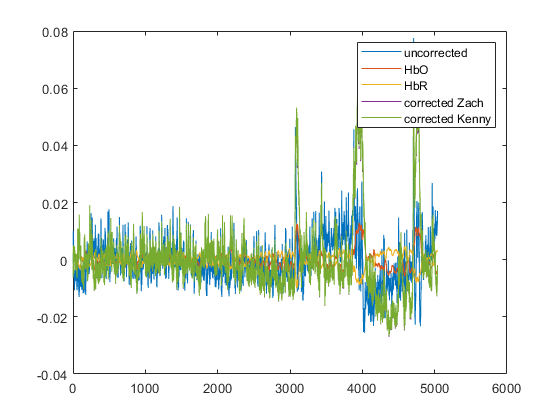

plot(squeeze(gcamp6(80,50,:)))
hold on;
plot(squeeze(hbData(80,50,1,:)))
plot(squeeze(hbData(80,50,2,:)))
plot(squeeze(gcamp6corr(80,50,:)))
plot(squeeze(fluorCorr(80,50,:)))
legend('uncorrected','HbO','HbR','corrected Zach','corrected Kenny')
hold off;